Simon Savukoski

First we will increase the sampling rate(interpolation) to L times the original. insertion. In interpolation, very high frequencies are added to the signal, and we remove them by low-pass filtering. When this is done, low-pass filtering is required again before decimation to prevent aliasing. After filtering, we can safely do the sampling rate reduction(decimation). In task 6 is interpolation and decimation is in task 7.

Task 6

clear variables
fs = 8192;
L=2;
M=3;
load laughter.mat y
soundsc(y, fs)
pause(7) %Pauses for 7 seconds, so you can hear each sample
z = zeros([length(y)*2,1]);
z(1:2:end) = y;
soundsc(z, L*fs);
pause(7)
h = fir1(100,1/L);
y2 = conv(h, z);
soundsc(y2, L*fs);
pause(7)

You can hear that there isn't so much crackle in the filtered signal y2. y2 sounds same as the original signal.

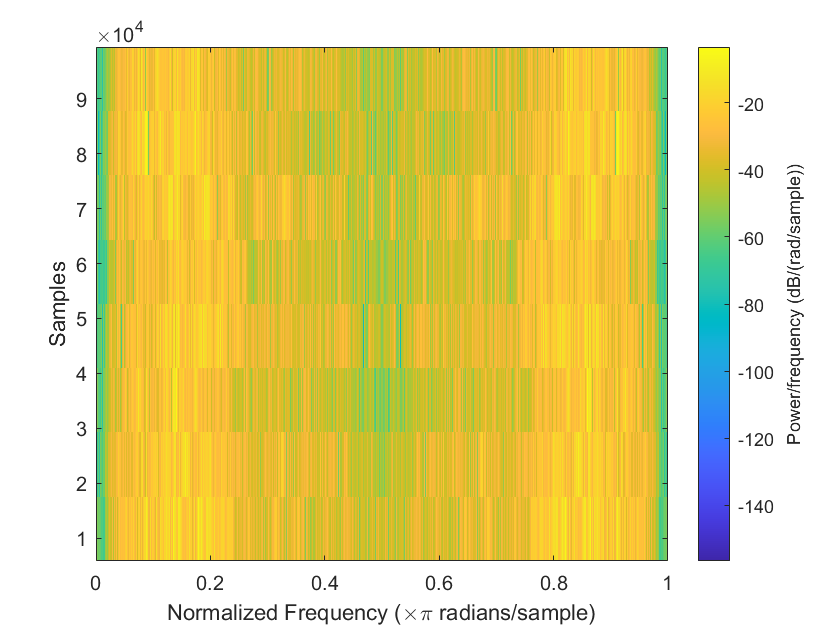

spectrogram(z)

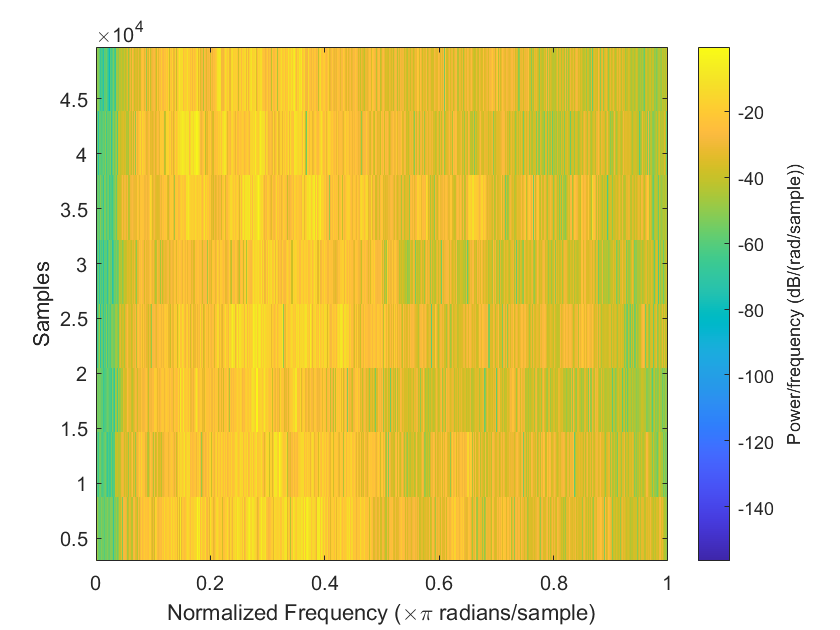

spectrogram(y)

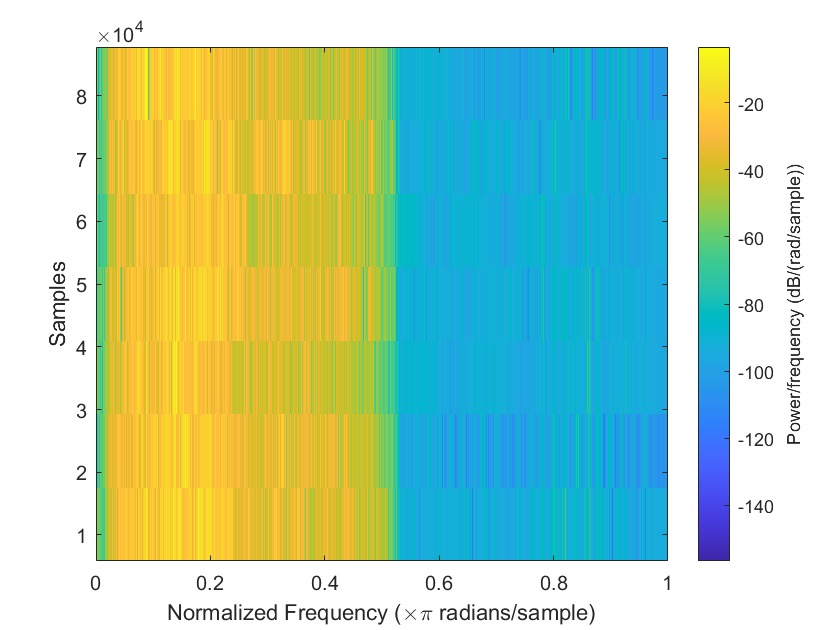

spectrogram(y2)

Task 7

h = fir1(100, 1/M);
y3 = conv(h, y2);
z=y3(1:3:end);
soundsc(z, fs*(L/M))
spectrogram(y2)

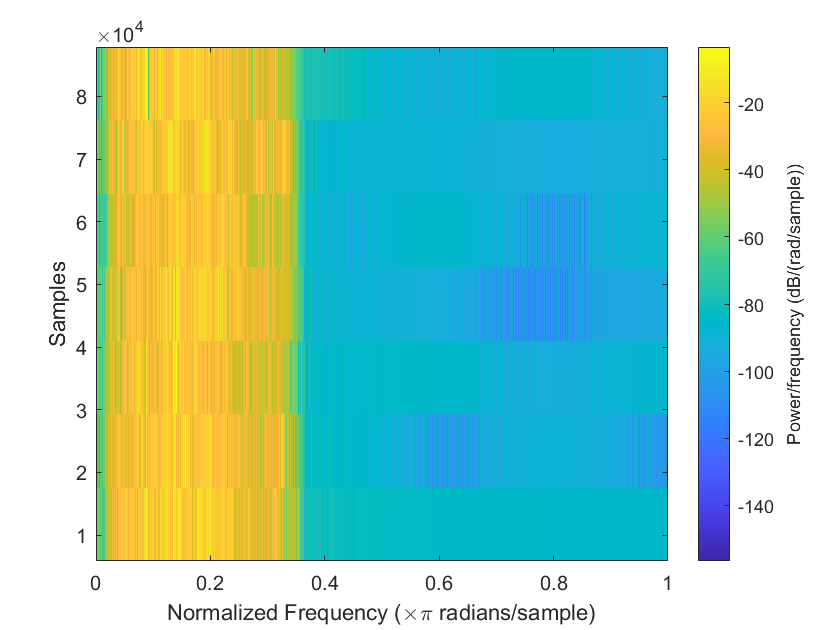

spectrogram(y3)

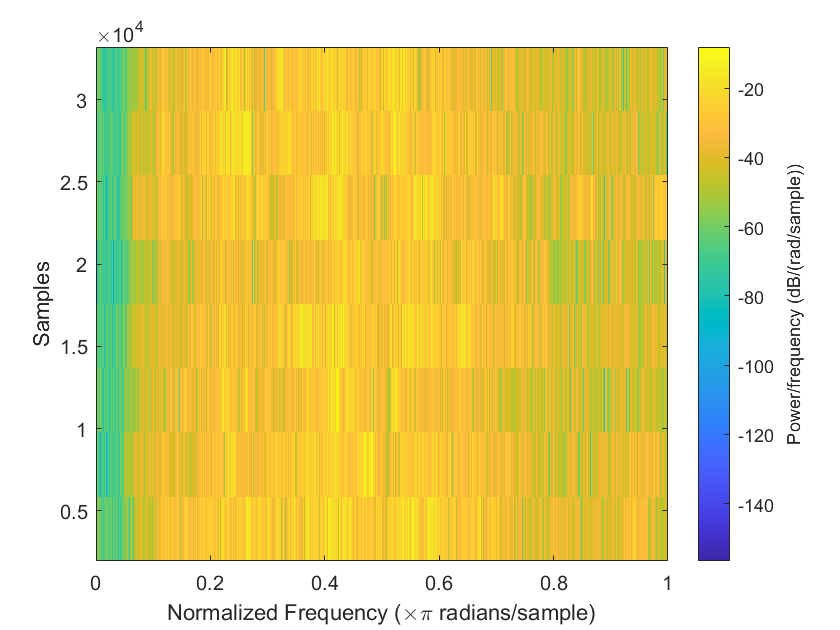

spectrogram(z)